% Parameters for the dataset
num_samples = 100; % Total number of samples
num_features = 2;  % Number of features
class_sep = 1;   % Degree of separability
rng(42);           % Set seed for reproducibility

% Generate random data for two classes
X_class1 = randn(num_samples/2, num_features) - class_sep; % Shift class 1
X_class2 = randn(num_samples/2, num_features) + class_sep; % Shift class 2

% Combine the two classes
X = [X_class1; X_class2];
y = [ones(num_samples/2, 1); -ones(num_samples/2, 1)]; % Labels (1 for class 1, -1 for class 2)

% Combine features and labels into one matrix
data = [X, y]

data =    -1.5382   -0.1996    1.0000
   -0.1328    0.1963    1.0000
   -0.0240    1.0975    1.0000
   -0.6626   -0.6123    1.0000
   -1.9961    0.0453    1.0000
   -1.5232   -2.3718    1.0000
   -2.2974   -1.9584    1.0000
   -0.0826   -3.6689    1.0000
   -0.8234   -1.8027    1.0000
   -0.2448   -1.4510    1.0000



% Write the data to a CSV file
csv_filename = 'synthetic_dataset.csv';
header = {'Feature1', 'Feature2', 'Label'};
fid = fopen(csv_filename, 'w');
fprintf(fid, '%s,%s,%s\n', header{:}); % Write header
fclose(fid);

% Append data
dlmwrite(csv_filename, data, '-append');

disp(['Dataset written to ', csv_filename]);

Dataset written to synthetic_dataset.csv


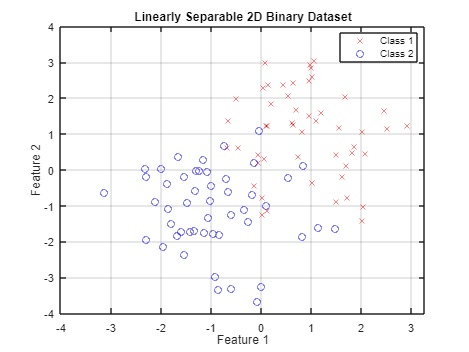


% Visualize the dataset
figure;
gscatter(X(:,1), X(:,2), y, 'rb', 'xo');
xlabel('Feature 1');
ylabel('Feature 2');
title('Linearly Separable 2D Binary Dataset');
legend('Class 1', 'Class 2');
grid on;